## **Author: MatNoble_HUST **

## **Date: 2019_6_2**

**Poisson Equation**


$$-\frac{d}{d x}\left(c(x) \frac{d u(x)}{d x}\right)=f(x), a<x<b$$


multiply v(x) and integral


$$-\int_{a}^{b} \frac{d}{d x}\left(c(x) \frac{d u(x)}{d x}\right) v(x) d x=\int_{a}^{b} f(x) v(x) d x$$


integration by parts 


$$-c(b) u^{\prime}(b) v(b)+c(a) u^{\prime}(a) v(a)+\int_{a}^{b} c u^{\prime} v^{\prime} d x=\int_{a}^{b} f v d x$$


and with dirichlet boundary condition, we have $v(a)=v(b)=0$. then


$$\int_{a}^{b} c u^{\prime} v^{\prime} d x=\int_{a}^{b} f v d x$$


$u(x)$is called a **trail function** and $v(x)$is called a **test function**.

i. e. **weak formulation**

find $u \in H^{1}(1)$ such that


$$a(u, v)=(f, v)$$
 

for any $v \in H_{0}^{1}(I)
$ where $I=(a, b)$.

further, **Galerkin formulation**

find $u_{h} \in U_{h}$ such that


$$a\left(u_{h}, v_{h}\right)=\left(f, v_{h}\right)$$



$$\Leftrightarrow \int_{a}^{b} c u_{h}^{\prime} v_{h}^{\prime} d x=\int_{a}^{b} f v_{h} d x$$


for any $v_{h} \in U_{h}^{0}$ where $I=(a, b)$.

% [N_s, error_max] = Poisson_1D(x1, xn, number_of_elements, p, basis_type, Gauss_type, Boundary_type)
% x1, x2 ： left and right endpoints
% number of mesh elements
% p : Degree of distortion
% basis_type : 
              % 101 : 1D linear
              % 102 : 1D quadratic
% Gauss_type : 2, 4, 8


## Example 1


$$u = x \, \text{cos}(x)$$


u = @(x)(x .* cos(x));


$$u_x = \text{cos}(x) - x\, \text{sin}(x)$$


u_x = @(x)(cos(x)-x*sin(x));


$$c = e^x$$


c = @(x)(exp(x));


$$f = -e^x\,[\text{cos}(x) - 2\, \text{cos}(x) - x\,\text{cos}(x) - x\,\text{sin}(x)]$$


f = @(x)(-exp(x) * (cos(x) - 2*sin(x) - x*cos(x) - x*sin(x)));

x1 = 0;    xn = 1;
number_of_elements = 64;
p = 0.4; 
basis_type = 101; % 1D linear
Gauss_type = 8;

disp("Example 1 with Dirichlet boundary conditions using linear basis")

Example 1 with Dirichlet boundary conditions using linear basis


solution1 =    -0.0000
    0.0231
    0.0389
    0.0558
    0.0655
    0.0776
    0.0932
    0.1124
    0.1304
    0.1405


error_max1 = 1.3432e-05

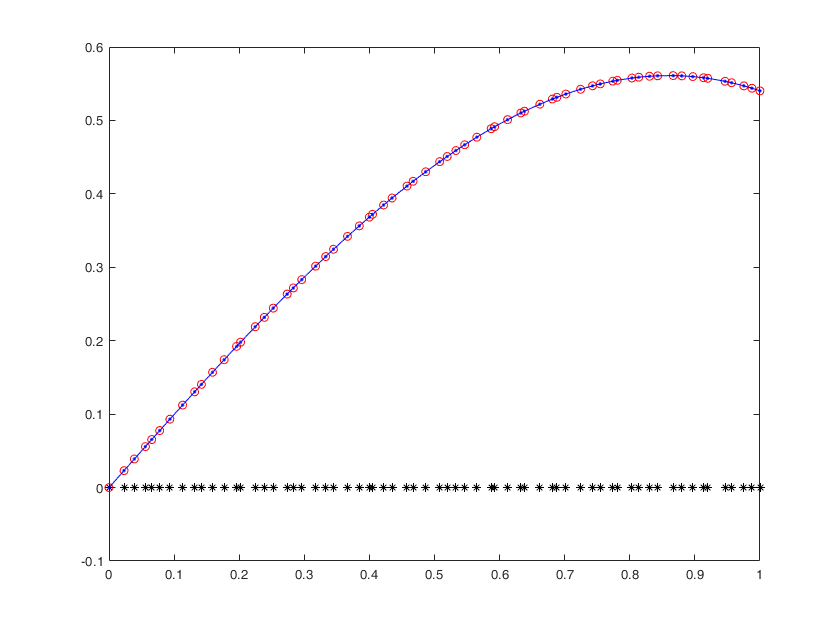

Boundary_type = [1, 1]; % Dirichlet
[solution1, error_max1] = Poisson_1D(u, u_x, c, f, x1, xn, number_of_elements,...
                                     p, basis_type, Gauss_type, Boundary_type)

disp("Example 1 with Neumann boundary conditions using linear basis")

Example 1 with Neumann boundary conditions using linear basis


 Boundary_type = [2, 1]; % Neumann
[solution12, error_max12] = Poisson_1D(u, u_x, c, f, x1, xn, number_of_elements,...
                                     p, basis_type, Gauss_type, Boundary_type)                              

solution12 =     0.0000
    0.0168
    0.0240
    0.0433
    0.0609
    0.0803
    0.0945
    0.1106
    0.1221
    0.1373


error_max12 = 3.3405e-05

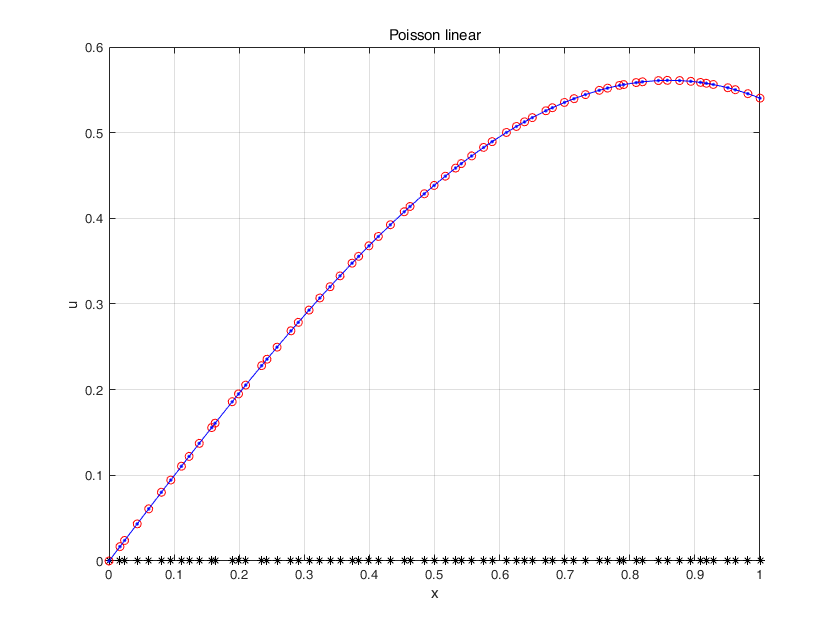

grid on
title('Poisson linear')
xlabel('x')
ylabel('u')



number_of_elements = 32;
basis_type = 102; % 1D quadratic

disp("Example 1 with linear boundary conditions using quadratic basis")

Example 1 with linear boundary conditions using quadratic basis


solution2 =    -0.0000
    0.0170
    0.0339
    0.0466
    0.0593
    0.0829
    0.1063
    0.1217
    0.1369
    0.1496


error_max2 = 6.2372e-08

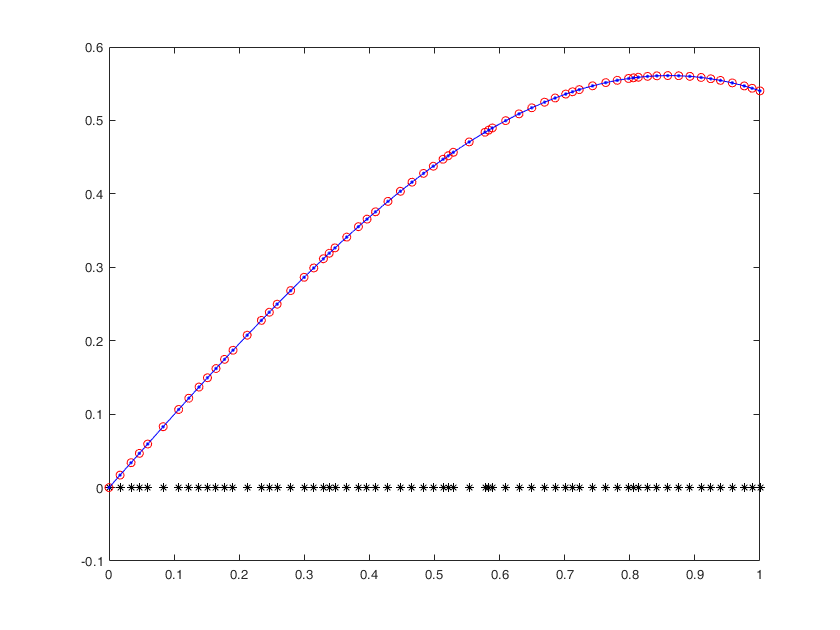

Boundary_type = [1, 1]; % Dirichle
[solution2, error_max2] = Poisson_1D(u, u_x, c, f, x1, xn, number_of_elements,...
                                     p, basis_type, Gauss_type, Boundary_type)

disp("Example 1 with Neumann boundary conditions using quadratic basis")

Example 1 with Neumann boundary conditions using quadratic basis


Boundary_type = [2, 1]; % Neumann
[solution22, error_max22] = Poisson_1D(u, u_x, c, f, x1, xn, number_of_elements,...
                                     p, basis_type, Gauss_type, Boundary_type)                                 

solution22 =    -0.0000
    0.0047
    0.0093
    0.0317
    0.0541
    0.0642
    0.0744
    0.0982
    0.1218
    0.1289


error_max22 = 5.9058e-08

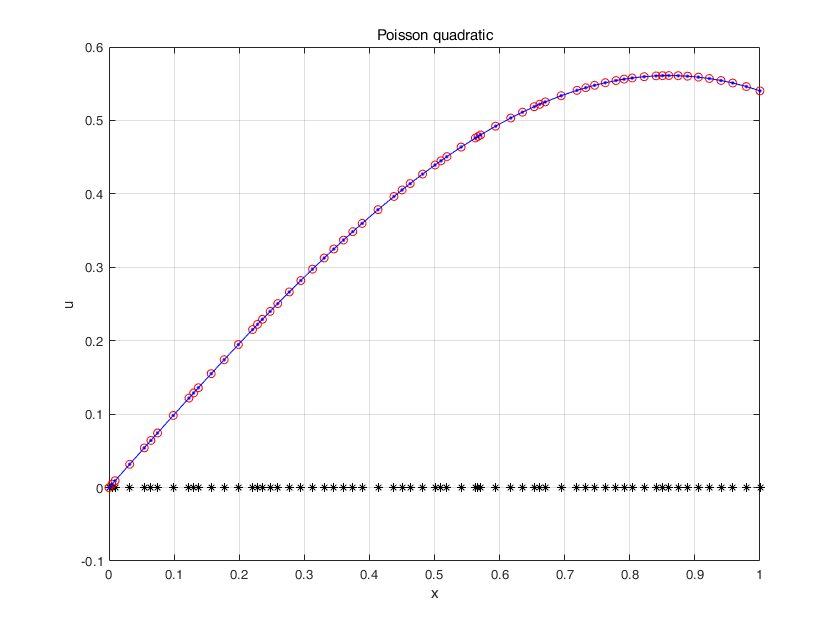

grid on
title('Poisson quadratic')
xlabel('x')
ylabel('u')